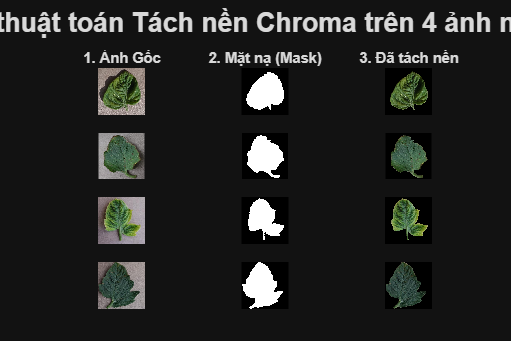

%% KIỂM THỬ THUẬT TOÁN TÁCH NỀN CHROMA
if ~exist('imds', 'var')
    imds = imageDatastore('data/raw/PlantVillage', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
end

numImagesToView = 4;
idx = randperm(numel(imds.Files), numImagesToView);

figure('Name', 'Kiểm thử Tách nền', 'Position', [100, 100, 1200, 800]);
sgtitle('Kiểm thử thuật toán Tách nền Chroma trên 4 ảnh ngẫu nhiên', 'FontSize', 16, 'FontWeight', 'bold');

for i = 1:numImagesToView
    img = imresize(imread(imds.Files{idx(i)}), [256 256]);

    [mask, result] = perform_chroma_segmentation(img);

    subplot(4, 3, (i-1)*3 + 1); imshow(img); if i == 1; title('1. Ảnh Gốc'); end
    subplot(4, 3, (i-1)*3 + 2); imshow(mask); if i == 1; title('2. Mặt nạ (Mask)'); end
    subplot(4, 3, (i-1)*3 + 3); imshow(result); if i == 1; title('3. Đã tách nền'); end
end

%% TRÍCH XUẤT ĐẶC TRƯNG HÀNG LOẠT VÀ LƯU RA FILE CSV
if ~exist('imds', 'var')
    imds = imageDatastore('PlantVillage', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
end

output_dir = 'dataset_segmented';
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

num_images = numel(imds.Files);
disp(['--- BẮT ĐẦU QUÁ TRÌNH TÁCH NỀN VÀ LƯU FILE (', num2str(num_images), ' ẢNH) ---']);

--- BẮT ĐẦU QUÁ TRÌNH TÁCH NỀN VÀ LƯU FILE (20638 ẢNH) ---



h = waitbar(0, 'Đang xử lý và lưu ảnh tách nền... Vui lòng đợi');

for i = 1:num_images
    img_path = imds.Files{i};
    
    class_name = char(imds.Labels(i));
    [~, name, ext] = fileparts(img_path);
    file_name = [name, ext];
    
    class_output_dir = fullfile(output_dir, class_name);
    if ~exist(class_output_dir, 'dir')
        mkdir(class_output_dir);
    end
    
    save_path = fullfile(class_output_dir, file_name);
    
    if exist(save_path, 'file') == 2
        continue;
    end
    
    img = imread(img_path);
    img = imresize(img, [256 256]);
    [~, result_rgb] = perform_chroma_segmentation(img);
    
    imwrite(result_rgb, save_path);
    
    if mod(i, 50) == 0
        waitbar(i / num_images, h, sprintf('Tiến độ lưu file: %d / %d ảnh...', i, num_images));
    end
end

close(h);
disp(['🎉 HOÀN TẤT! Toàn bộ ảnh đã được lưu sạch sẽ tại thư mục: ''', output_dir, '''']);

🎉 HOÀN TẤT! Toàn bộ ảnh đã được lưu sạch sẽ tại thư mục: 'dataset_segmented'


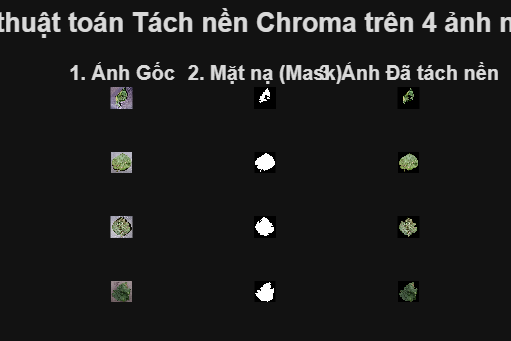

%% Hàm chứa thuật toán tách nền
function [mask, result] = perform_chroma_segmentation(img)
smoothed = imbilatfilt(img);
lab = rgb2lab(smoothed);
chroma = sqrt(lab(:,:,2).^2 + lab(:,:,3).^2);
chroma_norm = mat2gray(chroma);

level = graythresh(chroma_norm);
mask = imbinarize(chroma_norm, level);

mask = imopen(mask, strel('disk', 2));
mask = imclose(mask, strel('disk', 4));

if sum(mask(:)) > 0
    mask = bwareafilt(mask, 1);     
    mask = imfill(mask, 'holes');   
end

result = img;
result(repmat(~mask, [1 1 3])) = 0; 
end